# Read all the images 

%Change enable to 1 if you want to check the progression of image
%segmentation
enable=1;
if(enable==0)
    fprintf("Intermediate images will not be printed\n");
else
    fprintf("Intermediate images will be printed\n");
end

Intermediate images will be printed


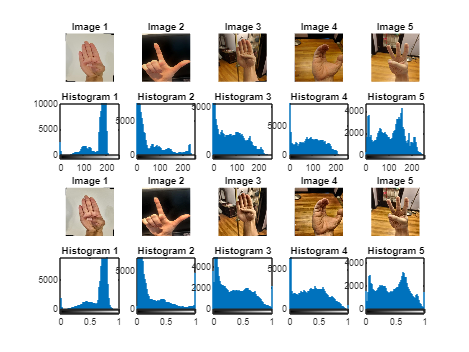


% Directory path
directory = 'Datasets\Task1\Images';
folderpath='Train';

% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.jpg'));

% Loop through the list and read each image
%If you want to test all the images just change the 5 for numel(fileList)
images = cell(1, numel(fileList)); % Initialize cell array to store images
images_eq = cell(1, numel(fileList));
images_squared = cell(1, numel(fileList));
list=[1 ,2 ,9 ,29 ,38 ];

for i = 1:numel(fileList) %
    % Get the file name
    fileName = fullfile(directory, fileList(i).name);
    
    % Read the image
    image = imread(fileName);
    
    % Store the image in the cell array
    
    images{i} = image;

    LAB = rgb2lab(image);
    L = LAB(:,:,1)/100;
    L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
    LAB(:,:,1) = L*100;
    J = lab2rgb(LAB);
    images_eq{i}=J;

end

% Display the images like a filmstrip
if(enable==1)
    figure;
    subplot(4,5,1);imshow(images{1});title('Image 1');
    subplot(4,5,2);imshow(images{2});title('Image 2');
    subplot(4,5,3);imshow(images{3});title('Image 3');
    subplot(4,5,4);imshow(images{4});title('Image 4');
    subplot(4,5,5);imshow(images{5});title('Image 5');
    subplot(4,5,6);imhist(images{1});title('Histogram 1');
    subplot(4,5,7);imhist(images{2});title('Histogram 2');
    subplot(4,5,8);imhist(images{3});title('Histogram 3');
    subplot(4,5,9);imhist(images{4});title('Histogram 4');
    subplot(4,5,10);imhist(images{5});title('Histogram 5');
    subplot(4,5,11);imshow(images_eq{1});title('Image 1');
    subplot(4,5,12);imshow(images_eq{2});title('Image 2');
    subplot(4,5,13);imshow(images_eq{3});title('Image 3');
    subplot(4,5,14);imshow(images_eq{4});title('Image 4');
    subplot(4,5,15);imshow(images_eq{5});title('Image 5');
    subplot(4,5,16);imhist(images_eq{1});title('Histogram 1');
    subplot(4,5,17);imhist(images_eq{2});title('Histogram 2');
    subplot(4,5,18);imhist(images_eq{3});title('Histogram 3');
    subplot(4,5,19);imhist(images_eq{4});title('Histogram 4');
    subplot(4,5,20);imhist(images_eq{5});title('Histogram 5');
end

## Parse the skin colour 

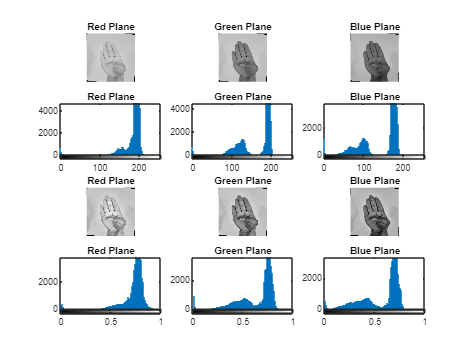

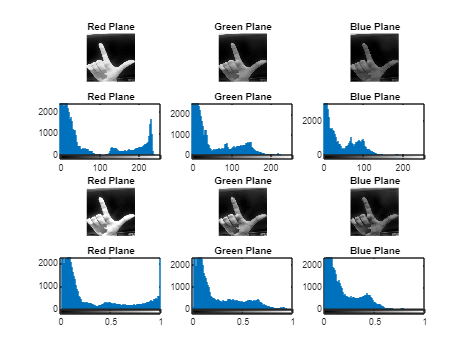

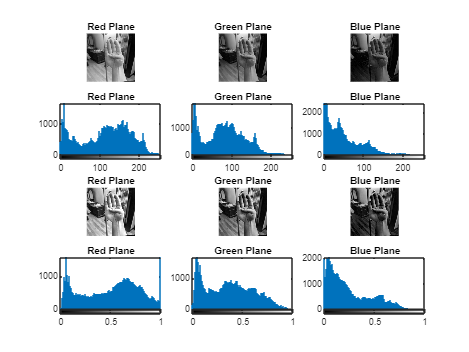

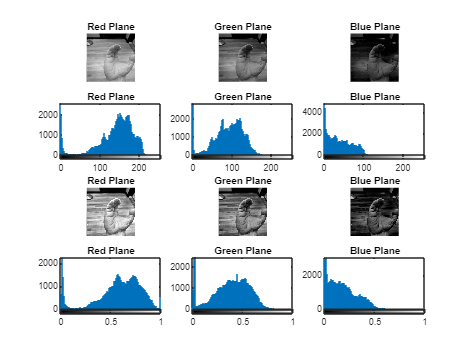

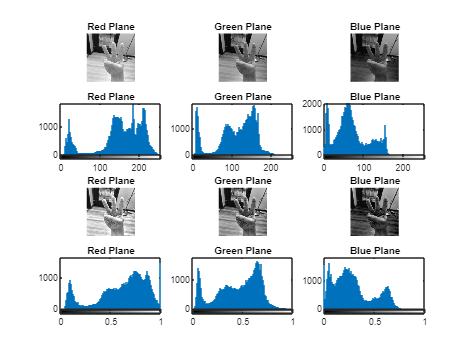

for n=1:5

    img=images{n};
    img2=images_eq{n};

    [R,G,B]=imsplit(img);
    [R2,G2,B2]=imsplit(img2);
    
    if(enable==1)
        figure();
        subplot(4,3,1);imshow(R);title('Red Plane');
        subplot(4,3,2);imshow(G);title('Green Plane');
        subplot(4,3,3);imshow(B);title('Blue Plane');
        subplot(4,3,4);imhist(R);title('Red Plane');
        subplot(4,3,5);imhist(G);title('Green Plane');
        subplot(4,3,6);imhist(B);title('Blue Plane');
        subplot(4,3,7);imshow(R2);title('Red Plane');
        subplot(4,3,8);imshow(G2);title('Green Plane');
        subplot(4,3,9);imshow(B2);title('Blue Plane');
        subplot(4,3,10);imhist(R2);title('Red Plane');
        subplot(4,3,11);imhist(G2);title('Green Plane');
        subplot(4,3,12);imhist(B2);title('Blue Plane');
    end

end

## Binarize the images

images_bin = cell(1, numel(fileList));
images_bin_eq = cell(1, numel(fileList));
for n=1:numel(fileList) 
    images_bin{n}=imbinarize(rgb2gray(images{n}));
    images_bin_eq{n}=imbinarize(rgb2gray(images_eq{n}));
end

if(enable==1)
    for i=1:numel(fileList)
        filename=strcat(sprintf('bin_%d.png',i));
        filename_eq=strcat(sprintf('bin_%d_eq.png',i));

        imwrite(images_bin{i},filename);
        imwrite(images_bin_eq{i},filename_eq);
    % subplot(1,5,1);imshow(images_bin{1});title("Image %d",i);
    % subplot(1,5,2);imshow(images_bin{2});title("Image 2");
    % subplot(1,5,3);imshow(images_bin{3});title("Image 9");
    % subplot(1,5,4);imshow(images_bin{4});title("Image 29");
    % subplot(1,5,5);imshow(images_bin{5});title("Image 38");
    end
end
